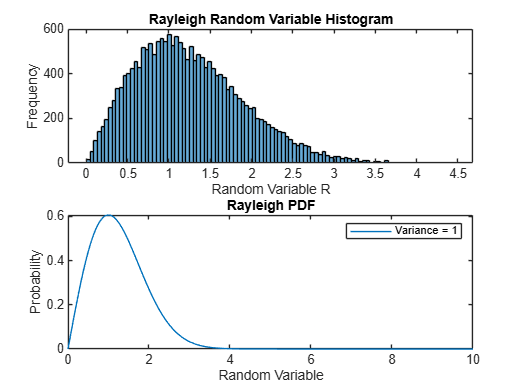

clc; clear; close all;

%% Parameters
N = 20000; % Number of bits
SNR_db = -5:0.5:35;
SNR = 10.^(SNR_db/10);
var = 1; % Variance
nstd = sqrt(var);

%% Generate Rayleigh Random Variable
u = rand(1, N);
r = sqrt(-2 * var * log(u));

figure;
subplot(2,1,1);
histogram(r, 100);
title('Rayleigh Random Variable Histogram');
xlabel('Random Variable R'); ylabel('Frequency');

a = 0:0.01:10;
R = (a / var) .* exp(-a.^2 / (2 * var));

subplot(2,1,2);
plot(a, R);
title('Rayleigh PDF'); xlabel('Random Variable'); ylabel('Probability');
legend('Variance = 1');

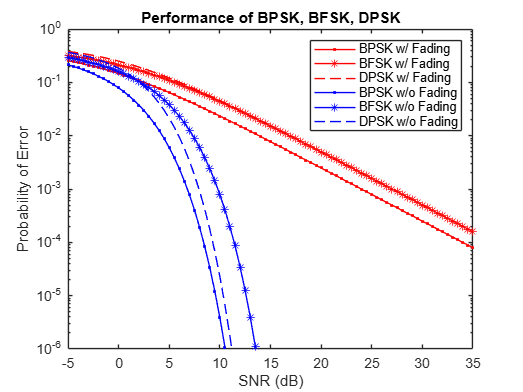


%% Theoretical BER Calculations
Pe_BPSK_id = 0.5 * (1 - sqrt((var * SNR) ./ (1 + var * SNR)));
Pe_BFSK_id = 0.5 * (1 - sqrt(var * SNR ./ (2 + var * SNR)));
Pe_DPSK_id = 0.5 ./ (1 + var * SNR);

Pe_BPSK_NF = 0.5 * erfc(sqrt(SNR));
Pe_BFSK_NF = 0.5 * erfc(sqrt(SNR / 2));
Pe_DPSK_NF = 0.5 * exp(-SNR);

%% Plot Performance Comparison
figure;
semilogy(SNR_db, Pe_BPSK_id, 'r.-', SNR_db, Pe_BFSK_id, 'r*-', SNR_db, Pe_DPSK_id, 'r--', ...
         SNR_db, Pe_BPSK_NF, 'b.-', SNR_db, Pe_BFSK_NF, 'b*-', SNR_db, Pe_DPSK_NF, 'b--');
axis([-5 35 1e-6 1]);
title('Performance of BPSK, BFSK, DPSK');
xlabel('SNR (dB)'); ylabel('Probability of Error');
legend('BPSK w/ Fading', 'BFSK w/ Fading', 'DPSK w/ Fading', ...
       'BPSK w/o Fading', 'BFSK w/o Fading', 'DPSK w/o Fading');

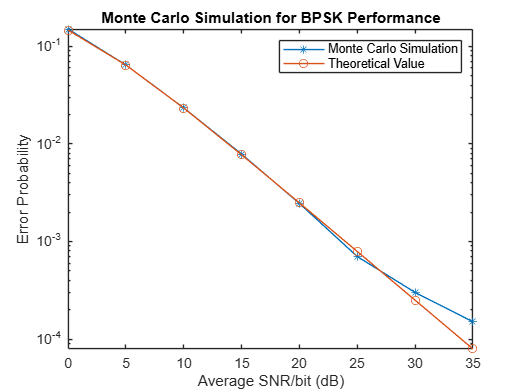


%% Monte Carlo Simulation for BPSK
EbNo_dB = 0:5:35;
Eb = 1;
No_over_2 = Eb * 10.^(-EbNo_dB / 10);
BER = zeros(1, length(EbNo_dB));

for i = 1:length(EbNo_dB)
    alpha = sqrt(-2 * log(rand(1, N)));
    noise = sqrt(No_over_2(i)) * randn(1, N);
    y = alpha * sqrt(Eb) + noise;
    BER(i) = sum(y <= 0) / N;
end

%% Theoretical BER
rho_b = Eb ./ No_over_2 * var;
P2 = 0.5 * (1 - sqrt(rho_b ./ (1 + rho_b)));

%% Monte Carlo vs Theoretical Plot
figure;
semilogy(EbNo_dB, BER, '-*', EbNo_dB, P2, '-o');
title('Monte Carlo Simulation for BPSK Performance');
xlabel('Average SNR/bit (dB)'); ylabel('Error Probability');
legend('Monte Carlo Simulation', 'Theoretical Value');